clc
clear
close all

## Defining the function:

f_x = @(y)(y);
f_y = @(x,y)(5*(1-x^2)*y-x);

## Defining r and dr

tFinal = 25;
dt = 0.01;
x0 = [1;0];

Nsteps = tFinal/dt;

K = sym('K',[4,1],'real');
syms xk yk real
syms dt  real;
A= [0.25 0.25-(sqrt(3)/6);0.25+(sqrt(3)/6) 1/4];
b1= [0.5 0.5];
s=2;
n=2;

for i = 1:s
    r(i,1) = subs(f_x(yk+dt*(A(i,1)*K(1)+A(i,2)*K(2)))-K(i));
    
end
for i = 1:s
    r(2+i,1) = subs(f_y(xk+dt*(A(i,1)*K(1)+A(i,2)*K(2)),yk+dt*(A(i,1)*K(3)+A(i,2)*K(4)))-K(2+i));
end

dr=jacobian(r,K);

rFileIRK4vdp=matlabFunction(r,dr,'Vars',{yk,xk,K,dt});


## Simulation:

Simulate using IRK4

tFinal = 25;
dt = 0.01;
x0 = [1;0];
Nsteps = tFinal/dt;
t = 0:dt:tFinal;
tIRK4=zeros(Nsteps,1);

xIRK4 = zeros(Nsteps,1);
yIRK4 = zeros(Nsteps,1);
xIRK4(1)=x0(1);
yIRK4(1)=x0(2);

K=[1;1;1;1];

%Here we compute the Newton iteration:
for k=1:Nsteps
    % Newton iteration
    iter = true;
    alpha = 1;
    niter = 0;
    while iter
        tIRK4(k+1) = tIRK4(k) + dt;
        [r,dr] = rFileIRK4vdp(yIRK4(k),xIRK4(k),K,dt);
        K = K - dr\r;
        
        norm(r);
        if norm(r) < 1e-5
            iter = false;
        else
            niter = niter + 1;
        end
    end
    K=reshape(K,[4,1]);
    yIRK4(k+1)=yIRK4(k)+dt*((b1(1)*K(2))+(b1(2)*K(4)));
    xIRK4(k+1)=xIRK4(k)+dt*((b1(1)*K(1))+(b1(2)*K(3)));
    
end
xIRK4_y=[xIRK4 yIRK4];

Simulate using ERK4

Plotting

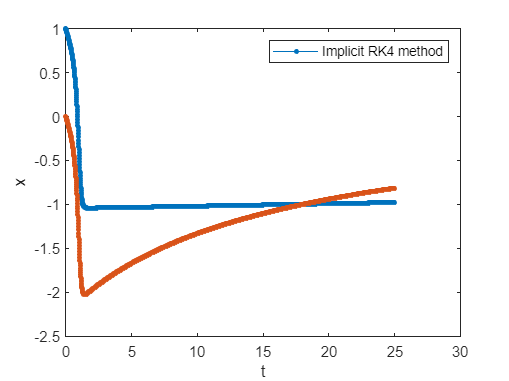

plot(tIRK4,xIRK4_y,'marker','.','markersize',10);
xlabel('t');
ylabel('x');
legend('Implicit RK4 method')